% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GROUP OPERATIONS
% some necessary functions-- need to convert this into a class
addpath 'Utility Functions'\ Data\;
% sympref('AbbreviateOutput',false); % the expressions are too long
syms x y theta u v beta real
M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);
L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); %%
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); %%
T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g); %%
g_vec = [x;
         y;
         theta]; %%
h_vec = [u;
         v;
         beta]; %%
g_mat = v2M_SE2(g_vec); %%
T_g_to_T_hg = T_gL_h(g_vec, h_vec); %%
T_g_to_T_gh = T_gR_h(g_vec, h_vec); %%
gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat); %%
TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)])); %%
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta])); %%
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10); %%
theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';
clear M2v_SE2; % has a conflict with a saved file

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CLARI KINEMATICS
syms a l alpha_b alpha_1 alpha_2 alpha_3 alpha_4 real
syms alpha_i real

% we shall directly use mCLARI measurements
ll = 19; % in mm
aa = 4.75/ll; % length fraction of the link to one side of the robot

% arbitrary leg transform
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];

% SE(2) transforms
h_b__1b = [ l*sin(alpha_b)/2,  l*cos(alpha_b)/2, alpha_b]'; % body frame to hip frame
h_b__2b = [-l*sin(alpha_b)/2,  l*cos(alpha_b)/2, pi-alpha_b]';
h_b__3b = [-l*sin(alpha_b)/2, -l*cos(alpha_b)/2, pi+alpha_b]';
h_b__4b = [ l*sin(alpha_b)/2, -l*cos(alpha_b)/2, -alpha_b]';

h_1b__1 = subs(h_ib__i, alpha_i, alpha_1); % hip frame to leg
h_2b__2 = subs(h_ib__i, alpha_i, alpha_2);
h_3b__3 = subs(h_ib__i, alpha_i, alpha_3);
h_4b__4 = subs(h_ib__i, alpha_i, alpha_4);

h_b__1 = simplify(seqSE2transformation([h_b__1b, h_1b__1])); % body frame to leg
h_b__2 = simplify(seqSE2transformation([h_b__2b, h_2b__2]));
h_b__3 = simplify(seqSE2transformation([h_b__3b, h_3b__3]));
h_b__4 = simplify(seqSE2transformation([h_b__4b, h_4b__4]));

h_b__12b = [              0,   l*cos(alpha_b),     alpha_b]'; % body frame to body sprawl joints
h_b__23b = [-l*sin(alpha_b),                0,  pi-alpha_b]';
h_b__34b = [              0,  -l*cos(alpha_b),  pi+alpha_b]';
h_b__41b = [ l*sin(alpha_b),                0,    -alpha_b]';

h_12b__1b = [0, -l*cos(alpha_b)/2, 0]'; % body sprawl joints to corresponding hip frames
h_12b__2b = simplify(seqSE2transformation( [[0, 0, pi-2*alpha_b]', [0, l*cos(alpha_b)/2, 0]'] ));
h_34b__3b = [0, -l*cos(alpha_b)/2, 0]';
h_34b__4b = simplify(seqSE2transformation( [[0, 0, pi-2*alpha_b]', [0, l*cos(alpha_b)/2, 0]'] ));

h_12b__1 = simplify(seqSE2transformation([h_12b__1b, h_1b__1])); % corresponding sprawl joints to legs
h_12b__2 = simplify(seqSE2transformation([h_12b__2b, h_2b__2]));
h_34b__3 = simplify(seqSE2transformation([h_34b__3b, h_3b__3]));
h_34b__4 = simplify(seqSE2transformation([h_34b__4b, h_4b__4]));

% defining unit velocities in theta SE(2) direction-- hip actuation velocities only include rotation
theta_dot = [0, 0, 1]';

% jacobians from body to leg
J_b__1 = AdjInvMap(h_b__1);
J_b__2 = AdjInvMap(h_b__2);
J_b__3 = AdjInvMap(h_b__3);
J_b__4 = AdjInvMap(h_b__4);

% jacobians from corresponding hip joints to each leg
J_1b__1 = AdjInvMap(h_1b__1);
J_2b__2 = AdjInvMap(h_2b__2);
J_3b__3 = AdjInvMap(h_3b__3);
J_4b__4 = AdjInvMap(h_4b__4);

% jacobians from sprawl joint to legs
J_12b__1 = AdjInvMap(h_12b__1);
J_12b__2 = AdjInvMap(h_12b__2);
J_34b__3 = AdjInvMap(h_34b__3);
J_34b__4 = AdjInvMap(h_34b__4);

% define the translational velocities selection matrix
Cxy = [eye(2,2), zeros(2,1)];

% full jacobians to each leg-- first 3 columns correspond to body velocity mapping; next 4 from each hip joint
J_1 = [J_b__1, J_12b__1*theta_dot, J_1b__1*theta_dot, zeros(3,3)];
J_2 = [J_b__2, J_12b__2*theta_dot, zeros(3,1), J_2b__2*theta_dot, zeros(3,2)];
J_3 = [J_b__3, J_34b__3*theta_dot, zeros(3,2), J_3b__3*theta_dot, zeros(3,1)];
J_4 = [J_b__4, J_34b__4*theta_dot, zeros(3,3), J_4b__4*theta_dot];

% pfaffian constraints governing the non-slip, level-2 contact states
pfaff_12 = [Cxy*J_1;
            Cxy*J_2];
pfaff_23 = [Cxy*J_2;
            Cxy*J_3];
pfaff_34 = [Cxy*J_3;
            Cxy*J_4];
pfaff_41 = [Cxy*J_4;
            Cxy*J_1];
pfaff_13 = [Cxy*J_1;
            Cxy*J_3];
pfaff_24 = [Cxy*J_2;
            Cxy*J_4];

% squared inter-leg distance field F
gt_12 = Cxy*(h_b__2 - h_b__1);
gt_23 = Cxy*(h_b__3 - h_b__2);
gt_34 = Cxy*(h_b__4 - h_b__3);
gt_41 = Cxy*(h_b__1 - h_b__4);
gt_13 = Cxy*(h_b__3 - h_b__1);
gt_24 = Cxy*(h_b__4 - h_b__2);
F_12 = simplify(transpose(gt_12)*gt_12, "Steps", 10);
F_23 = simplify(transpose(gt_23)*gt_23, "Steps", 10);
F_34 = simplify(transpose(gt_34)*gt_34, "Steps", 10);
F_41 = simplify(transpose(gt_41)*gt_41, "Steps", 10);
F_13 = simplify(transpose(gt_13)*gt_13, "Steps", 10);
F_24 = simplify(transpose(gt_24)*gt_24, "Steps", 10);

% normalized gradient of F-- direction of strongest slip
gradF_12 = simplify(gradient(F_12, [alpha_b, alpha_1, alpha_2])); norm_gradF_12 = norm(gradF_12); gradF_12 = simplify(gradF_12/norm_gradF_12);
gradF_23 = simplify(gradient(F_23, [alpha_b, alpha_2, alpha_3])); norm_gradF_23 = norm(gradF_23); gradF_23 = simplify(gradF_23/norm_gradF_23);
gradF_34 = simplify(gradient(F_34, [alpha_b, alpha_3, alpha_4])); norm_gradF_34 = norm(gradF_34); gradF_34 = simplify(gradF_34/norm_gradF_34);
gradF_41 = simplify(gradient(F_41, [alpha_b, alpha_4, alpha_1])); norm_gradF_41 = norm(gradF_41); gradF_41 = simplify(gradF_41/norm_gradF_41);
gradF_13 = simplify(gradient(F_13, [alpha_b, alpha_1, alpha_3])); norm_gradF_13 = norm(gradF_13); gradF_13 = simplify(gradF_13/norm_gradF_13);
gradF_24 = simplify(gradient(F_24, [alpha_b, alpha_2, alpha_4])); norm_gradF_24 = norm(gradF_24); gradF_24 = simplify(gradF_24/norm_gradF_24);

% the local connections for each of these contact states-- overconstrained first 4x3 matrix needs to be pseudoinverted
A_12 = simplify(  (transpose(pfaff_12(:,1:3))*pfaff_12(:,1:3) )\transpose(pfaff_12(:,1:3)) *pfaff_12(:,4:end), "Steps", 20  );
A_23 = simplify(  (transpose(pfaff_23(:,1:3))*pfaff_23(:,1:3) )\transpose(pfaff_23(:,1:3)) *pfaff_23(:,4:end), "Steps", 20  );
A_34 = simplify(  (transpose(pfaff_34(:,1:3))*pfaff_34(:,1:3) )\transpose(pfaff_34(:,1:3)) *pfaff_34(:,4:end), "Steps", 20  );
A_41 = simplify(  (transpose(pfaff_41(:,1:3))*pfaff_41(:,1:3) )\transpose(pfaff_41(:,1:3)) *pfaff_41(:,4:end), "Steps", 20  );
A_13 = simplify(  (transpose(pfaff_13(:,1:3))*pfaff_13(:,1:3) )\transpose(pfaff_13(:,1:3)) *pfaff_13(:,4:end), "Steps", 20  );
A_24 = simplify(  (transpose(pfaff_24(:,1:3))*pfaff_24(:,1:3) )\transpose(pfaff_24(:,1:3)) *pfaff_24(:,4:end), "Steps", 20  );

% extract the "$alpha_b_dot" components (4th column) from each connection and replace them with the corresponding terms in limb swing velocity directions
rA_12 = reduce_2beatgait_noslip_connection(A_12, 1, 2, gradF_12);
rA_23 = reduce_2beatgait_noslip_connection(A_23, 2, 3, gradF_23);
rA_34 = reduce_2beatgait_noslip_connection(A_34, 3, 4, gradF_34);
rA_41 = reduce_2beatgait_noslip_connection(A_41, 4, 1, gradF_41);
rA_13 = reduce_2beatgait_noslip_connection(A_13, 1, 3, gradF_13);
rA_24 = reduce_2beatgait_noslip_connection(A_24, 2, 4, gradF_24);

% Let's create functions and load all of this into a kinematics structure
clari_kin = []; clari_kin.params = []; clari_kin.sym = []; clari_kin.functions = [];

clari_kin.params.aa = aa;
clari_kin.params.ll = ll;

cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];
clari_kin.cSubmanifolds = cs;

% clari_kin.sym.h_b__1b = h_b__1b;
% clari_kin.sym.h_b__2b = h_b__2b;
% clari_kin.sym.h_b__3b = h_b__3b;
% clari_kin.sym.h_b__4b = h_b__4b;
% clari_kin.sym.h_1b__1 = h_1b__1;
% clari_kin.sym.h_2b__2 = h_2b__2;
% clari_kin.sym.h_3b__3 = h_3b__3;
% clari_kin.sym.h_4b__4 = h_4b__4;
% clari_kin.sym.h_b__1 = h_b__1;
% clari_kin.sym.h_b__2 = h_b__2;
% clari_kin.sym.h_b__3 = h_b__3;
% clari_kin.sym.h_b__4 = h_b__4;
% clari_kin.functions.h_b__1b_f = matlabFunction(h_b__1b, "Vars", [a l alpha_b]);
% clari_kin.functions.h_b__2b_f = matlabFunction(h_b__2b, "Vars", [a l alpha_b]);
% clari_kin.functions.h_b__3b_f = matlabFunction(h_b__3b, "Vars", [a l alpha_b]);
% clari_kin.functions.h_b__4b_f = matlabFunction(h_b__4b, "Vars", [a l alpha_b]);
% clari_kin.functions.h_1b__1_f = matlabFunction(h_1b__1, "Vars", [a l alpha_b alpha_1]);
% clari_kin.functions.h_2b__2_f = matlabFunction(h_2b__2, "Vars", [a l alpha_b alpha_2]);
% clari_kin.functions.h_3b__3_f = matlabFunction(h_3b__3, "Vars", [a l alpha_b alpha_3]);
% clari_kin.functions.h_4b__4_f = matlabFunction(h_4b__4, "Vars", [a l alpha_b alpha_4]);
% clari_kin.functions.h_b__1_f = matlabFunction(h_b__1, "Vars", [a l alpha_b alpha_1]);
% clari_kin.functions.h_b__2_f = matlabFunction(h_b__2, "Vars", [a l alpha_b alpha_2]);
% clari_kin.functions.h_b__3_f = matlabFunction(h_b__3, "Vars", [a l alpha_b alpha_3]);
% clari_kin.functions.h_b__4_f = matlabFunction(h_b__4, "Vars", [a l alpha_b alpha_4]);
for i = 1:4                                                                                 % does everything above in a loop and "fstring" kinda way
    % Symbolic Transforms
    clari_kin.sym. ...
        (['h_b__' num2str(i) 'b']) = eval(['h_b__' num2str(i) 'b']);
    clari_kin.sym. ...
        (['h_' num2str(i) 'b__' num2str(i)]) = eval(['h_' num2str(i) 'b__' num2str(i)]);
    clari_kin.sym. ...
        (['h_b__' num2str(i)]) = eval(['h_b__' num2str(i)]);
    % Functional transforms
    clari_kin.functions. ...
        (['h_b__' num2str(i) 'b_f']) = matlabFunction(eval(['h_b__' num2str(i) 'b']), "Vars", [a l alpha_b]);
    clari_kin.functions. ...
        (['h_' num2str(i) 'b__' num2str(i) '_f']) = matlabFunction(eval(['h_' num2str(i) 'b__' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['h_b__' num2str(i) '_f']) = matlabFunction(eval(['h_b__' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
end
clari_kin.sym.h_b__12b = h_b__12b;
clari_kin.sym.h_b__23b = h_b__23b;
clari_kin.sym.h_b__34b = h_b__34b;
clari_kin.sym.h_b__41b = h_b__41b;
clari_kin.sym.h_b__12b_f = matlabFunction(h_b__12b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__23b_f = matlabFunction(h_b__23b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__34b_f = matlabFunction(h_b__34b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__41b_f = matlabFunction(h_b__41b, "Vars", [a l alpha_b]);

% clari_kin.sym.pfaff_12 = pfaff_12;
% clari_kin.sym.pfaff_23 = pfaff_23;
% clari_kin.sym.pfaff_34 = pfaff_34;
% clari_kin.sym.pfaff_41 = pfaff_41;
% clari_kin.sym.pfaff_13 = pfaff_13;
% clari_kin.sym.pfaff_24 = pfaff_24;
% clari_kin.functions.pfaff_12_f = matlabFunction(pfaff_12, "Vars", [a l alpha_b alpha_1 alpha_2]);
% clari_kin.functions.pfaff_23_f = matlabFunction(pfaff_23, "Vars", [a l alpha_b alpha_2 alpha_3]);
% clari_kin.functions.pfaff_34_f = matlabFunction(pfaff_34, "Vars", [a l alpha_b alpha_3 alpha_4]);
% clari_kin.functions.pfaff_41_f = matlabFunction(pfaff_41, "Vars", [a l alpha_b alpha_4 alpha_1]);
% clari_kin.functions.pfaff_13_f = matlabFunction(pfaff_13, "Vars", [a l alpha_b alpha_1 alpha_3]);
% clari_kin.functions.pfaff_24_f = matlabFunction(pfaff_24, "Vars", [a l alpha_b alpha_2 alpha_4]);
% clari_kin.sym.F_12 = F_12;
% clari_kin.sym.F_23 = F_23;
% clari_kin.sym.F_34 = F_34;
% clari_kin.sym.F_41 = F_41;
% clari_kin.sym.F_13 = F_13;
% clari_kin.sym.F_24 = F_24;
% clari_kin.functions.F_12_f = matlabFunction(F_12, "Vars", [a l alpha_b alpha_1 alpha_2]);
% clari_kin.functions.F_23_f = matlabFunction(F_23, "Vars", [a l alpha_b alpha_2 alpha_3]);
% clari_kin.functions.F_34_f = matlabFunction(F_34, "Vars", [a l alpha_b alpha_3 alpha_4]);
% clari_kin.functions.F_41_f = matlabFunction(F_41, "Vars", [a l alpha_b alpha_4 alpha_1]);
% clari_kin.functions.F_13_f = matlabFunction(F_13, "Vars", [a l alpha_b alpha_1 alpha_3]);
% clari_kin.functions.F_24_f = matlabFunction(F_24, "Vars", [a l alpha_b alpha_2 alpha_4]);
% clari_kin.sym.gradF_12 = gradF_12;
% clari_kin.sym.gradF_23 = gradF_23;
% clari_kin.sym.gradF_34 = gradF_34;
% clari_kin.sym.gradF_41 = gradF_41;
% clari_kin.sym.gradF_13 = gradF_13;
% clari_kin.sym.gradF_24 = gradF_24;
% clari_kin.functions.gradF_12_f = matlabFunction(gradF_12, "Vars", [a l alpha_b alpha_1 alpha_2]);
% clari_kin.functions.gradF_23_f = matlabFunction(gradF_23, "Vars", [a l alpha_b alpha_2 alpha_3]);
% clari_kin.functions.gradF_34_f = matlabFunction(gradF_34, "Vars", [a l alpha_b alpha_3 alpha_4]);
% clari_kin.functions.gradF_41_f = matlabFunction(gradF_41, "Vars", [a l alpha_b alpha_4 alpha_1]);
% clari_kin.functions.gradF_13_f = matlabFunction(gradF_13, "Vars", [a l alpha_b alpha_1 alpha_3]);
% clari_kin.functions.gradF_24_f = matlabFunction(gradF_24, "Vars", [a l alpha_b alpha_2 alpha_4]);
% clari_kin.functions.norm_gradF_12_f = matlabFunction(norm_gradF_12, "Vars", [a l alpha_b alpha_1 alpha_2]);
% clari_kin.functions.norm_gradF_23_f = matlabFunction(norm_gradF_23, "Vars", [a l alpha_b alpha_2 alpha_3]);
% clari_kin.functions.norm_gradF_34_f = matlabFunction(norm_gradF_34, "Vars", [a l alpha_b alpha_3 alpha_4]);
% clari_kin.functions.norm_gradF_41_f = matlabFunction(norm_gradF_41, "Vars", [a l alpha_b alpha_4 alpha_1]);
% clari_kin.functions.norm_gradF_13_f = matlabFunction(norm_gradF_13, "Vars", [a l alpha_b alpha_1 alpha_3]);
% clari_kin.functions.norm_gradF_24_f = matlabFunction(norm_gradF_24, "Vars", [a l alpha_b alpha_2 alpha_4]);
% clari_kin.sym.A_12 = A_12;
% clari_kin.sym.A_23 = A_23;
% clari_kin.sym.A_34 = A_34;
% clari_kin.sym.A_41 = A_41;
% clari_kin.sym.A_13 = A_13;
% clari_kin.sym.A_24 = A_24;
% clari_kin.functions.A_12_f = matlabFunction(A_12, "Vars", [a l alpha_b alpha_1 alpha_2]);
% clari_kin.functions.A_23_f = matlabFunction(A_23, "Vars", [a l alpha_b alpha_2 alpha_3]);
% clari_kin.functions.A_34_f = matlabFunction(A_34, "Vars", [a l alpha_b alpha_3 alpha_4]);
% clari_kin.functions.A_41_f = matlabFunction(A_41, "Vars", [a l alpha_b alpha_4 alpha_1]);
% clari_kin.functions.A_13_f = matlabFunction(A_13, "Vars", [a l alpha_b alpha_1 alpha_3]);
% clari_kin.functions.A_24_f = matlabFunction(A_24, "Vars", [a l alpha_b alpha_2 alpha_4]);

for i = 1:size(cs,1)
    % pfaffian constraints
    clari_kin.sym.(['pfaff_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['pfaff_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions. ...
        (['pfaff_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['pfaff_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))])] ); % func
    % scalar field F
    clari_kin.sym.(['F_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['F_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions.(['F_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['F_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % func
    % contact submanifold information-- easier to save this elementwise
        % gradient of F in the shape space
    clari_kin.sym.(['gradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['gradF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym var
    clari_kin.sym.(['norm_gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['norm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
    clari_kin.functions.(['gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['gradF_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    for j = 1:numel(gradF_12)
        clari_kin.functions.(['gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % compute and store func var elementwise
    end
        % local connection
    clar_kin.sym.(['A_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['A_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clar_kin.sym.(['rA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['rA_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.functions.(['A_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['A_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['A_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['A_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['A_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['A_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['rA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['rA_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['rA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['rA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['rA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['rA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
end

% Save the data
if exist('Data\4clari', 'file')
    save('Data\4clari', "a", "l", "alpha_b", "alpha_1", "alpha_2", "alpha_3", "alpha_4", "alpha_i", ... % set up in such a way that symbolic variables will be directly loaded into the workspace
        "clari_kin", "append");
else
    save('Data\4clari', "a", "l", "alpha_b", "alpha_1", "alpha_2", "alpha_3", "alpha_4", "alpha_i", ...
        "clari_kin");
end

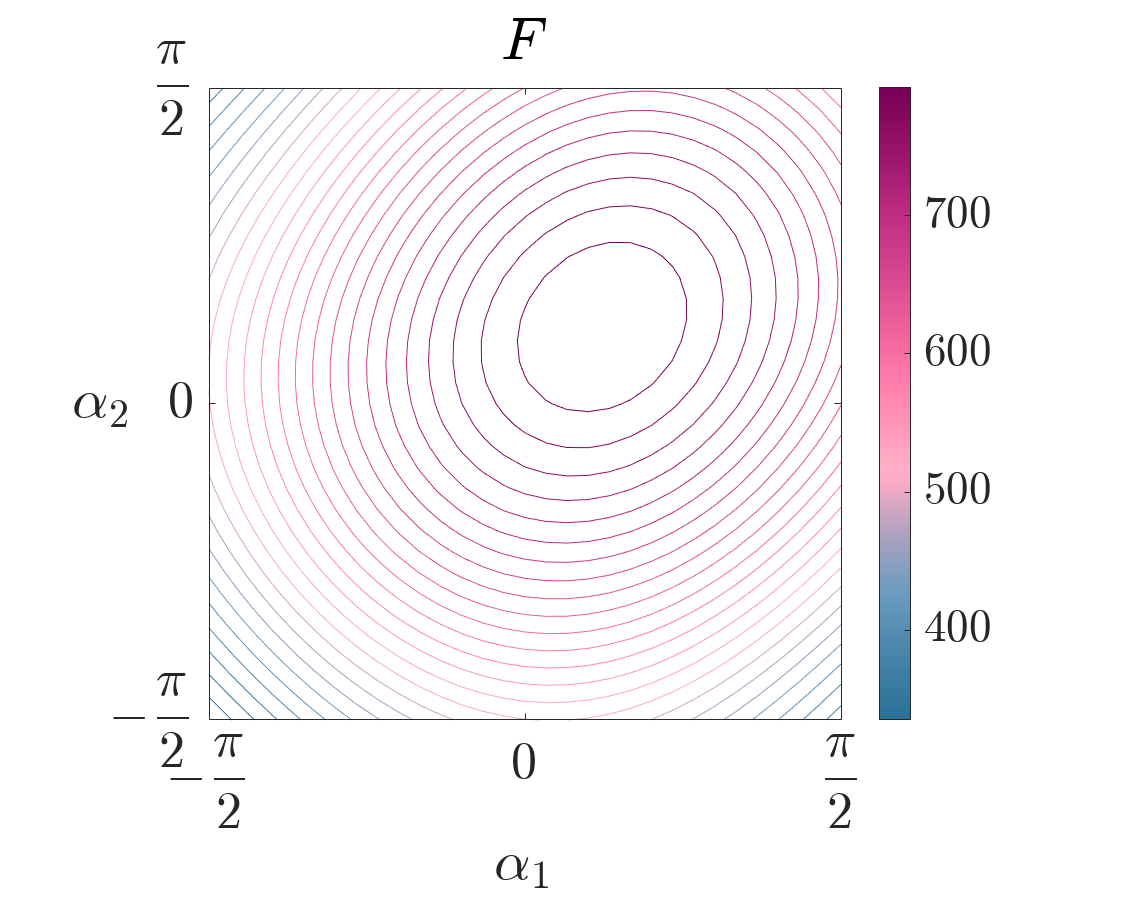

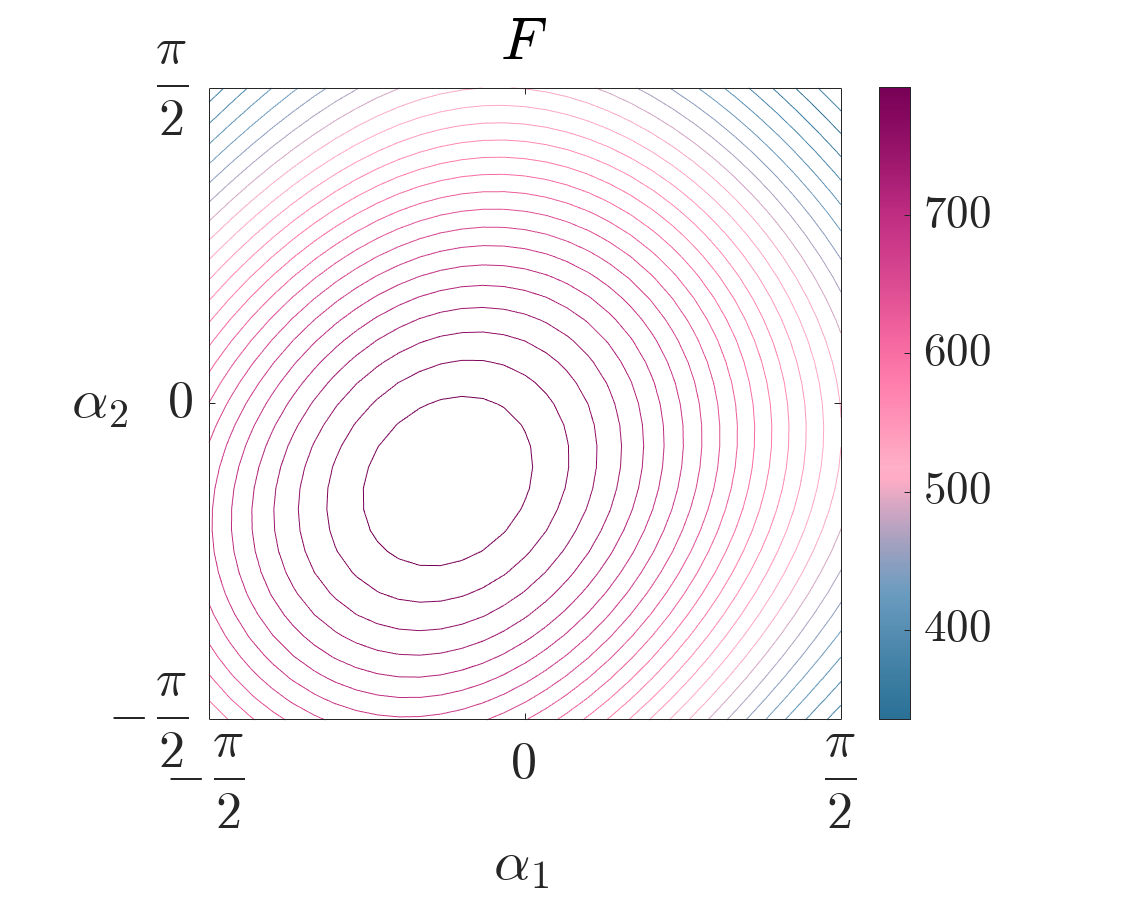

% load paths and data
addpath 'Utility Functions'\ Data\; load Data\4clari.mat;

% shape-space discretization ----------------------------------------------
dnum = 31; % 1001 is used in the previous sections
            % use multiples of 10 with a +1 at the end

% plot parameters ---------------------------------------------------------
skipV = 7.5; % PERCENTAGE OF THE DISCRETIZATION POINTS TO SKIP for connection
sV = 10; % for gait constraint % previous 7.5
skipV = round((skipV/100)*2*floor(dnum/2)); sV = round((sV/100)*2*floor(dnum/2));
cLvl = 25; % number of contour levels -- ksq
cfLvl = 100; % number of filled contour levels
fontscale = 1.25; % use this scale number to change the font in the plot
                  % preferred range [0.5 2.5]; start iterating at 1.25
fA = 1.00; % transparency of heat maps
           % some vals to try: 0.50 % 1.00 % 0.40 % 0.75

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% compute data for plotting -----------------------------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Colors and Colormaps
cmap_custom = flipud([174,1,126;
           221,52,151;
           247,104,161;
           250,159,181;
           116,169,207;
           54,144,192])/255;
cmap_custom = interp1(linspace(0,100,size(cmap_custom,1)), cmap_custom, linspace(0,100,size(jet,1)));
jP = sqrt(cmap_custom(:,1).^2 + cmap_custom(:,2).^2 + cmap_custom(:,3).^2);
jS = 1.1;
cmap_custom = jS/max(jP)*repmat(jP,1,3).*cmap_custom; 
cmap_custom(cmap_custom > 1) = 1; % condition it to be one at most when scaled
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])/255;
CUB = interp1(linspace(0,100,size(CUB,1)), CUB, linspace(0,100,size(turbo,1)));
col = (1/255)*[255,127,0;
                        231,41,138;
                        44,123,182;
                        77,175,74;
                        215,25,28;
                        96,0,220;
                        72,72,72];
col_backg = [255,255,255]/255;

% LineStyle
lW_c = (1.0*10)/cLvl;
lW_Vector = (1.0/10)*skipV; % vector linewidth % (1.0/100) previous
lW_V = (1.0/10)*sV; % (1.0/100) previous

% skipping indices when plotting vector fields
itQ = 1:skipV:dnum;
iQ = 1:sV:dnum;

% text and text style
ksq_title_text = "$$F$$";
dpsi_title_text = "$$(\Delta \alpha)_{F}$$";
A_title_txt = cell(1, 3); 
A_title_txt{1} = "$$-\vec{\mathbf{A}}^{x}$$"; 
A_title_txt{2} = "$$-\vec{\mathbf{A}}^{y}$$"; 
A_title_txt{3} = "$$-\vec{\mathbf{A}}^{\theta}$$";
dz_title_txt = cell(1, 3); 
dz_title_txt{1} = "$$dz^{x}$$"; 
dz_title_txt{2} = "$$dz^{y}$$"; 
dz_title_txt{3} = "$$dz^{\theta}$$";
x_label_txt = '$$\alpha_{1}$$';
y_label_txt = '$$\alpha_{2}$$';
tickFS = 21*fontscale; labelFS = 21*fontscale; titleFS = 24*fontscale; cbarFS = 18*fontscale;

% Set the default interpreter before plotting to latex
%%%% https://www.mathworks.com/matlabcentral/answers/346436-how-to-use-latex-interpreter-for-xticklabels
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% shape space discretization
ai = linspace(-pi/2, pi/2, dnum); aj = ai; ab = deg2rad(linspace(34, 56, dnum)); % leg and leg j shapes along with the body shape
xlimits = [ai(1) ai(end)]; ylimits = [aj(1) aj(end)]; zlimits = [ab(1) ab(end)]; 
[ai, aj, ab] = meshgrid(ai, aj, ab);
xtickval = -pi/2:pi/2:pi; ytickval = xtickval;
xticklab = {'$$-\frac{\pi}{2}$$','$$0$$','$$\frac{\pi}{2}$$', '$$\pi$$'}; yticklab = xticklab;

% unpack
aa = clari_kin.params.aa;
ll = clari_kin.params.ll;
F_13_f = clari_kin.functions.F_13_f;
gradF_13_f = clari_kin.functions.gradF_13_f;

% scalar fields needed for S13
F_13_sweep = F_13_f(aa, ll, ab, ai, aj);

% plot the scalar field
f = figure('units', 'pixels', 'position', [0 0 750 600], 'Color','w'); set(f,'Visible','on'); axis equal;
scatter3(ai(:), aj(:), ab(:), F_13_sweep(:), F_13_sweep(:), "filled", "MarkerEdgeColor", "none", "MarkerFaceAlpha", 0.125);
colormap(cmap_custom); colorbar();

% f = figure('units', 'pixels', 'position', [0 0 750 600], 'Color','w');
% ax = gca;
% for i = 1:dnum
%     if i~= 1
%         cla(ax);
%     end
%     % get the current data slice
%     aiNow =         reshape(        ai(:, :, i), [dnum, dnum]); 
%     ajNow =         reshape(        aj(:, :, i), [dnum, dnum]);
%     F_13_sweepNow = reshape(F_13_sweep(:, :, i), [dnum, dnum]);
%     % plot the contour
%     p = contour(ax, aiNow, ajNow, F_13_sweepNow, cLvl,'LineWidth',lW_c);
%     if i == 1
%         axis equal tight; hold on; view(2);
%         colormap(ax, cmap_custom); colorbar(ax, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS); %%%%%%%%%%%%%%%%%%%%%%%%%%%
%         set(get(ax, 'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
%         title(ax, ksq_title_text, FontSize=titleFS);
%         xticks(ax, xtickval); yticks(ax, ytickval);
%         xticklabels(ax, xticklab);
%         yticklabels(ax, xticklab);
%         xlabel(ax, x_label_txt, FontSize=labelFS); ylabel(ax, y_label_txt, FontSize=labelFS);
%         ax.XAxis.FontSize = tickFS; ax.YAxis.FontSize = tickFS; set(ax, 'Color', col_backg);
%         xlim(ax, xlimits); ylim(ax, ylimits);
%     end
%     % get the output
%     drawnow;
% end